# Coursework 1

## Predicting survival in the Titanic disaster

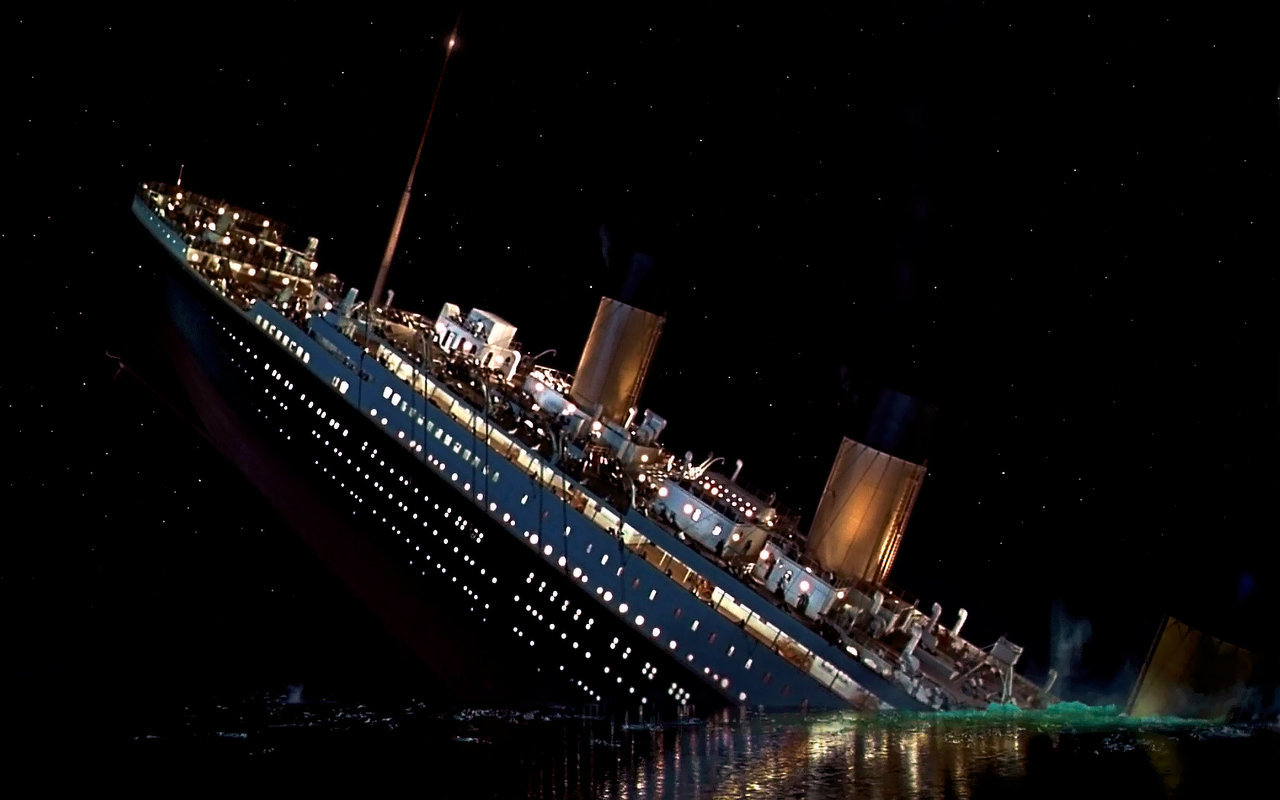

**Summary: **On 15 April 1912, the RMS Titanic ship struck an iceberg and sank. Of the estimated 2224 passengers on board over 1500 died. This led to significant changes in maritime safety regulations. With modern AI tools we can go further and ask 'what sort of passenger was most likely to survive'?  This type of information could help identify shortcomings in safety and processes.  For this coursework you will build a classifier, based on decision trees and random forests, that will predict whether or not a passenger would survive. You will report back on the key attributes that determine survival. You will be given a partial passenger list, containing multiple data points for each passenger and whether or not they survived, to train your model.  Part of the assessment will be to run the model on unseen passenger data and predict survival.

**Marks:** 25% of module mark. Marking rubric is on Moodle. Marks and feedback will be provided 15 working days after the submission deadline; each student will receive an individual copy of the marking rubric posted on Moodle by email. If required, further individual feedback is then available by requesting a one-to-one meeting.

**Submission: **MATLAB live script (.mlx) plus any functions (.m) or live functions (.mlx) files used. To be submitted via Moodle - put **ALL** your files into a single .zip archive that can be unzipped into a folder and then run.

**Deadline: **Thursday 19 March 3pm

**Estimated time required: **~40 hours

**Files: **The file passengers.csv contains a list of some of the passengers and their details (attributes).  The attributes provided are described in the file attributes.pdf.

**Note about copying code: **We may use MOSS ([http://theory.stanford.edu/~aiken/moss/](http://theory.stanford.edu/~aiken/moss/)) to check for similarity between pieces of code - both with other students and with code available online.  Please WRITE YOUR OWN CODE and do not just copy from online examples - you will get zero if you are found doing this.

## Part 1: Data analysis and plotting (25%)

To start with, make sure you can load the data and can plot it.  For example:

clc;
close all;
clear variables;

passengerData = readtable('passengers.csv');

We can then plot a pie chart of the sex of those who died:

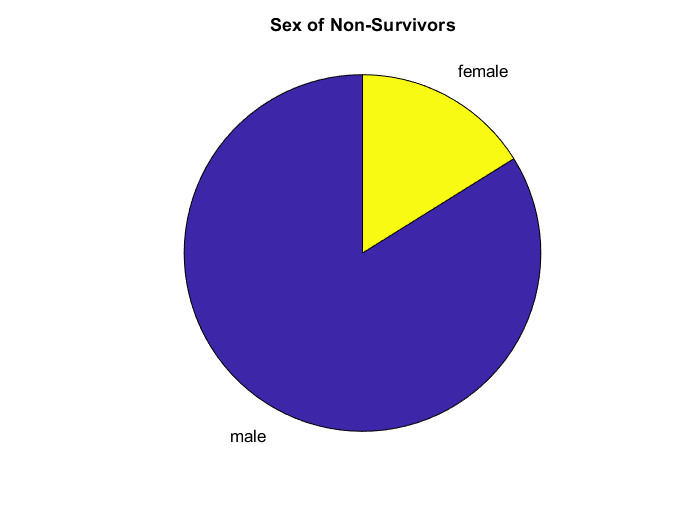

passengers=size(passengerData(:,1));
passengerSex = passengerData.sex;
passengerSurvival = passengerData.survived;

% Produce a logical type ('true' or 'false') list indicating those who survived
survivors = (passengerSurvival == 1);

% Sex of those who did not survive
sexOfNonSurvivors = passengerSex(~survivors); 
maleNonSurvivors = strcmp(sexOfNonSurvivors,'male');
nMaleNonSurvivors = sum(maleNonSurvivors); 

% Number of male non-survivors
nFemaleNonSurvivors = sum(~maleNonSurvivors);

% Pie Chart - Sex of Non-Survivors
pie([nMaleNonSurvivors,nFemaleNonSurvivors],{'male','female'})
title('Sex of Non-Survivors')

### Tasks:

1. Plot two pie charts: the first should show the gender split of survivors and the second should show the gender split of all passenger

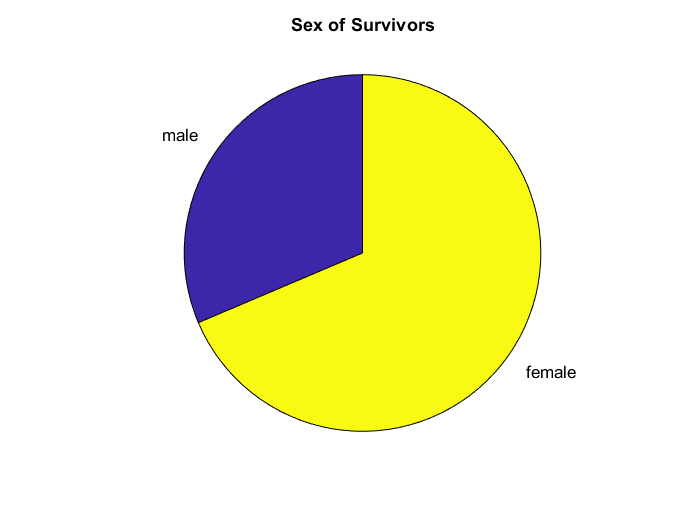

% Sex of those who did survive
sexOfSurvivors = passengerSex(survivors); 
MaleSurvivors=strcmp(sexOfSurvivors,'male');

% Number of male and female survivors
nMaleSurvivors = sum(MaleSurvivors); 
nFemaleSurvivors = sum(~MaleSurvivors);

% Pie Chart - Sex of Survivors
pie([nMaleSurvivors,nFemaleSurvivors],{'male','female'});
title('Sex of Survivors');

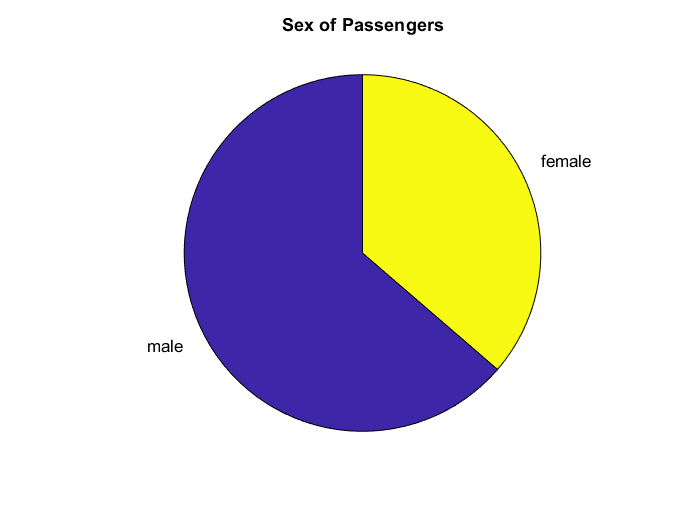

% Gender split of all Passengers regardless of survival
malePassengers = strcmp(passengerData.sex,'male');
nMale= sum(malePassengers);
nFemale= sum(~malePassengers);

% Pie Chart - Sex of Passengers
pie([nMale,nFemale],{'male','female'});
title('Sex of Passengers');

What trends do you observe?

*Females survived more, even though there were more male passengers on board *

2. Plot two histograms: the first should show of the ages of survivors and the second should show the ages of non-survivors.  You may find the following functions useful:

and

For information on how to use these function type:

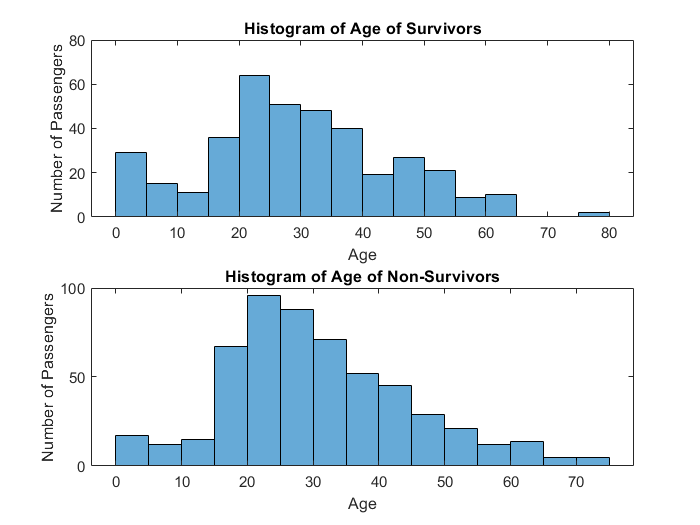

passengerAge=passengerData.age; % Initialise Passenger Age Variable

% Produce a logical type ('true' or 'false') list indicating those who
% survived's age
survivorsAge = (passengerSurvival == 1); 

ageOfSurvivors = passengerAge(survivorsAge); %Sex of those who did not survive

ageOfNonSurvivors = passengerAge(~survivorsAge);

% Histogram Subplot
figure
subplot(2,1,1)
histogram(ageOfSurvivors) % Histogram: Age of Survivors
title('Histogram of Age of Survivors')
xlabel('Age')
ylabel('Number of Passengers')

subplot(2,1,2)
histogram(ageOfNonSurvivors) % Histogram: Age of Non-Survivors
title('Histogram of Age of Non-Survivors')
xlabel('Age')
ylabel('Number of Passengers')

What trends do you observe from these histograms?

*Children were more likely to survive, proven with a higher spike seen in the ages of 20 and above. Above the age of 40 more people were counted as non-survivors.*

3. Many passenger entries in the dataset do not contain entries in all fields: for example 'age' is often missing. Calculate the proportion of passengers in each of first, second and third class whose age data is not known and plot this data in bar chart.  The x-axis should be 'class of travel' and the y-axis should be 'proportion of passengers with missing age data'. Note that blank entries in the raw CSV file (if opened in Excel) correspond to `NaN` entries in MATLAB.  You might find the following function useful:

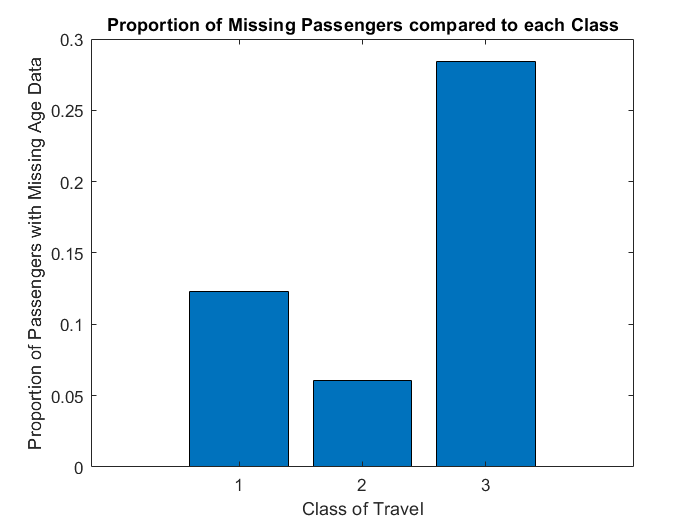

firstclass=0; secondclass=0; thirdclass=0; % Initialise passenger class variables

% for loop identifying amount of passengers in each class
for i=1:1159
    if passengerData.pclass(i)==1
        firstclass=firstclass+1;
    elseif passengerData.pclass(i)==2
        secondclass=secondclass+1;
    else 
        thirdclass=thirdclass+1;
    end
end

% Initialise variable with a logical array identifying missing age 
MissingAgeData=isnan(passengerAge);

% Initialise missing passenger class variables 
MissingAgeFirstClass=0; MissingAgeSecondClass=0; MissingAgeThirdClass=0;

% for loop identifying amount of missing passengers in each class
for i=1:1159
    if MissingAgeData(i)==1&&passengerData.pclass(i)==1
        MissingAgeFirstClass=MissingAgeFirstClass+1;
    elseif MissingAgeData(i)==1&&passengerData.pclass(i)==2
        MissingAgeSecondClass=MissingAgeSecondClass+1;
    elseif MissingAgeData(i)==1&&passengerData.pclass(i)==3
        MissingAgeThirdClass=MissingAgeThirdClass+1;
    end
end

% Bar Chart: Proportion of Missing Passengers/Class
figure
x=[1 2 3];
y=[MissingAgeFirstClass/firstclass, MissingAgeSecondClass/secondclass, MissingAgeThirdClass/thirdclass];
bar(x,y)
title('Proportion of Missing Passengers compared to each Class')
xlabel('Class of Travel')
ylabel('Proportion of Passengers with Missing Age Data')

## Part 2: Dealing with missing data (25%)

Given the large proportion of missing data, we must find a strategy to train a classifier without introducing *bias - *for example, it might be that older people were less likely to divulge their age to the ticketing office. To do this, we could simply exclude all data points that are missing values but this has a critical problem - we might need to classify a new data point that has missing data.  We therefore need a more robust strategy. This part will explore three strategies for dealing with missing data.

### Tasks

1. *Method 1: *Generate a copy of the *passengerData* dataset, called *passengerData_av*.  For this new data set, write some code that for each of the attributes `{'age', 'fare', 'embarked'}` finds any missing values and replaces them with an average value. For continuous values, e.g. `'age'`, use the mean.  You will need to consider what a suitable averaging method for categorical values such as `'pclass'` might be.

You may find the following functions useful:

To get the name of the variable associated with column `colIdx` of a table you can use:

To check if data is a 'numerical' type use:

To check if a 'string' type variable is empty use:

Other functions you might find useful:

passengerData_Avg=passengerData; % Initialise new variable for Average data

passengerData_Avg_age=nanmean(passengerData_Avg.age); % Identify average age ignoring missing values
passengerData_Avg.age(isnan(passengerData_Avg.age))=passengerData_Avg_age; % Replace every missing age value with average age

passengerData_Avg_fare=nanmean(passengerData_Avg.fare); % Identify average fare ignoring missing values
passengerData_Avg.fare(isnan(passengerData_Avg.fare))=passengerData_Avg_fare; % Replace every missing fare value with average fare

mode_embarked=mode(categorical(passengerData_Avg.embarked)); % Identifies the mode of the embarked results
missingEmbarkedData=find(strcmpi(passengerData_Avg.embarked,'')); % Identified missing embarked data - Row: 253
passengerData_Avg.embarked{missingEmbarkedData,:}=char(mode_embarked); % Replaces every missing row with mode_embarked

2. *Method 2:* This method finds the 'most similar' data point and copies over the missing value from that. This is called the 'nearest neighbour' approach. We need to consider how to compute the similarity (or distance) between data points that contain a mixture of numerical and categorical values. Here, we will use MATLABs built-in function:

*Note: *you need to have installed the Bioinformatics Toolbox to use this function.  

Generate a copy of the `passengerData` dataset, called `passengerData_nn`, that uses `knnimpute` to fill in missing values for the attributes `{'age', 'fare', 'embarked'}`.  You will first need to select only the relevant columns from the original data set.  You will also need to convert some columns to a categorical datatype.  You may find the following function useful:

passengerData_nn=passengerData; % Initialise new variable for Nearest Neighbour data

[category_num category_chr]=grp2idx(passengerData_nn.embarked); % Categorise Data into {1,2,3} depending on category

% KNN Impute to replace the missing categorical value in embarked with passenger class
passengerData_nn_embarkedpclass=knnimpute([category_num passengerData_nn.pclass],2); 

% KNN Impute to replace the missing value using previous impute results.
% To improve results, other classes with no missing variables used to 
% more accurately predict numerical continous values of age and fare
passengerData_nn_revised=knnimpute([passengerData_nn_embarkedpclass(:,2) passengerData_nn.survived passengerData_nn.age passengerData_nn.sibsp passengerData_nn.parch passengerData_nn.fare  passengerData_nn_embarkedpclass(:,1)],7);

passengerData_nn.embarked=string(passengerData_nn_embarkedpclass(:,1)); % Convert to string

% for loop replacing numerical results back to original embarked categories
for i=1:size(passengerData,1)
    if passengerData_nn.embarked(i)=="1"
        passengerData_nn.embarked(i)=category_chr(1,:); % S
    elseif passengerData_nn.embarked(i)=="2"
        passengerData_nn.embarked(i)=category_chr(2,:); % C
    elseif passengerData_nn.embarked(i)=="3"
        passengerData_nn.embarked(i)=category_chr(3,:); % Q 
    end
end

passengerData_nn.embarked=categorical(passengerData_nn.embarked); % Convert to Categorical

% Replace old data to new impute data
passengerData_nn.age=passengerData_nn_revised(:,3); 
passengerData_nn.fare=passengerData_nn_revised(:,6);

3. In task 2 you may have noticed that there is one value missing from the `'fare'` attribute.  Compare your estimated values for the missing fare using the average approach and the nearest neighbour approach. Which do you think is more realistic given the other information about the passenger?

*Missing Fare is on the row 1095. *

*With the nearest neighbour the fare is 12.271 and with average it is 33.6085. *

*The neighbour approach seems better due to the fact it uses more data samples to compute its result whereas, the latter takes just the average to calculate the missing value.*

4. *Method 3: *In this case you will create new attributes that determine whether or not the data is missing. For example, you will create a new variable called  `'is_age_missing'`.  Generate a copy of the `passengerData` dataset, `passengerData_newAttr`, that contains new attributes indicating a missing value for the attributes `{'age', 'boat', 'body'}.  `These will be called `is_age_missing``, ``is_boat_missing`, and `is_body_missing `respectively.

% Initialise new variable using age boat and body from passenger data
passengerData_newAttrTest=passengerData(:,["age" "boat" "body"]);
passengerData_newAttrTest.Properties.VariableNames=["Age_Missing" "Boat_Missing" "Body_Missing"];

Is_Missing=strcmpi(passengerData_newAttrTest.Boat_Missing, ''); %Identify missing boat missing as logical array

% Convert and initialise each variable to a string array
passengerData_newAttr_Age_Missing=string(passengerData_newAttrTest.Age_Missing);
passengerData_newAttr_Body_Missing=string(passengerData_newAttrTest.Body_Missing);
passengerData_newAttr_Boat_Missing=string(passengerData_newAttrTest.Boat_Missing);

% for all passenger data
for i=1:size(passengerData,1)
    
    % Age Missing: Replace each age missing with Yes/No from logical array
    if isnan(passengerData_newAttrTest.Age_Missing(i))==1
       passengerData_newAttr_Age_Missing(i)='Yes';
    else
        passengerData_newAttr_Age_Missing(i)='No';
    end
    
    % Body Missing: Replace each body missing with Yes/No from logical array
    if isnan(passengerData_newAttrTest.Body_Missing(i))==1
        passengerData_newAttr_Body_Missing(i)='Yes';
    else
        passengerData_newAttr_Body_Missing(i)='No';
    end
    
    % Boat Missing: Replace each boat missing with Yes/No from logical array
    if Is_Missing(i)==1
        passengerData_newAttr_Boat_Missing(i)='Yes';
    else
        passengerData_newAttr_Boat_Missing(i)='No';
    end
end

% Initialise struct with each Age, Body and Body Missing
passengerData_newAttrStruct.AgeMissing=(passengerData_newAttr_Age_Missing);
passengerData_newAttrStruct.BoatMissing=(passengerData_newAttr_Boat_Missing);
passengerData_newAttrStruct.BodyMissing=(passengerData_newAttr_Body_Missing);

passengerData_newAttrTable=struct2table(passengerData_newAttrStruct); % Convert struct to table
passengerData_newAttr=[passengerData passengerData_newAttrTable]; % Add variables to original passenger data

## Part 3: Computing entropy (25%)

### Tasks:

1. Write a function that takes as input an array containing data class (i.e. whether a passenger survived or not), and a list of all possible data classes ('survived' or 'not survived' here - represented by `1` or `0`), and computes the entropy.  It should have the following form:

This should be in a new file called *calcEnt.m* (or *calcEnt.mlx *if you prefer).  To check that it works, run the following:

testIn = categorical([1,1,1,1,0,0,0,0,1,0,0,0,0]');
classList = categories(testIn);
testCalcEnt = calcEnt(testIn,classList)

testCalcEnt = 0.9612

The result should be:

You may find the notes from Lectures 1 and 2 helpful.

2. a) Write another function that takes as input a continuous valued column of data, the associated data classes, and a threshold value and returns the information gain for splitting at that threshold.  Your function should have the following form:

This should be in a new file called *calcEntThresh.m* (or *calcEntThresh.mlx* if you prefer). Your code should call the `calcEnt` function you wrote in task 1 to calcuate the total entropy and the specific conditional entropy above and below the split. To confirm your code is correct, run the following:

ageData_test = [10,11,12,17,25,46,48,49,50];
dataClass_test = [0,0,0,1,1,1,0,0,0];
threshVal_test = 20;
testEnt = calcEntThresh(ageData_test,dataClass_test,threshVal_test)

testEnt = 0.0183

The result should be:

Next, run the following code on the age variable from your passengerData`_av `data to compute the information gain for a threshold of 5:

ageData = passengerData_Avg.age;
dataClass = passengerData_Avg.survived;
threshVal = 5;
testEnt = calcEntThresh(ageData,dataClass,threshVal)

testEnt = 0.0073

The result should be:

b) Using your `calcEntThreshFunction`, plot the information gain when splitting on age at thresholds every 0.5 years from 0 to 100. The x-axis should be age threshold and the y-axis should be information gain.

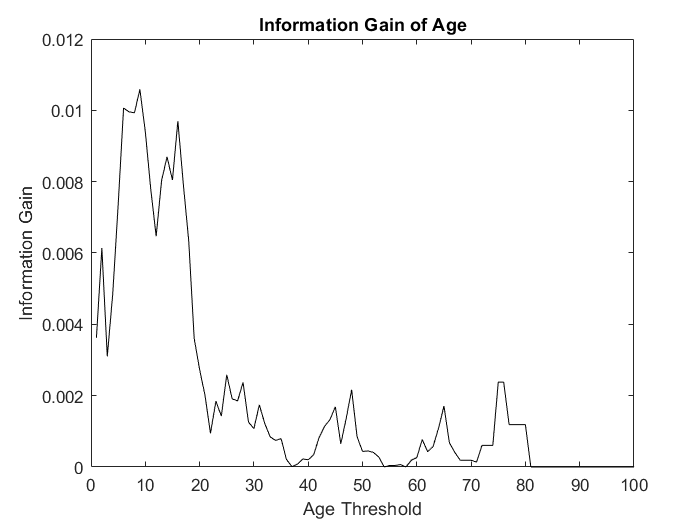

threshAgeSplit = [0:0.5:100]'; % Initialise the Age Split from 0-100 every 0.5 years (transposed)

AgeThreshEnt = zeros(numel(threshAgeSplit)); % Preallocate data to save memory

% for loop to calculate the entropy threshold of each age every 0.5 from 0 to 100
for i=1:size(threshAgeSplit)
    AgeThreshEnt(i) = calcEntThresh(ageData,dataClass,i);
end

% Line Plot: Information Gain over Age from 0 to 100 (0.5)
plot(1:numel(threshAgeSplit),AgeThreshEnt(:,1),'k')
xlim([0 100]) %NB: No age should be present at 0
title('Information Gain of Age')
xlabel('Age Threshold')
ylabel('Information Gain')

To the nearest year, what is the optimal threshold to split the `age` variable? Justify your answer.

*9 years is the visible peak, this is probably due to amount of number of above and below values to be large.*

3. Write another function that takes as input a categorical valued column of data, the associated data classes, and an array of target categories. It should return the information gain for splitting the data into items that are in one of the target categories and items that are not. Your function should have the following form:

The `dataClass` variable will again be whether or not each data point 'survived'. The function should be in a new file called *calcEntCat.m* (or *calcEntCat.mlx* if you prefer). Your code should call the `calcEnt` function you wrote previously to calcuate the total entropy and the specific conditional entropy for each case. You might find the following function useful:

You may also find the following functions useful:

To test your function run the following code:

dataCat_test = {'dog','dog','cat','cat','cat','fish','fish','fish','fish'};
dataCat_test = categorical(dataCat_test);
dataClass_test = [1,0,1,0,1,0,1,0,1];
dataClass_check = {'fish'};
testEnt = calcEntCat(dataCat_test,dataClass_test,dataClass_check)

testEnt = 0.0072

The result should be:

Next, run your code on the `pclass` variable to compute the information gain for being in first class:

pclassData = passengerData_Avg.pclass;
dataClass = passengerData_Avg.survived;
pclassCheck = [1];
testEnt = calcEntCat(pclassData,dataClass,pclassCheck)

testEnt = 0.0568

The result should be 

4. Using your modified data table, `passengerData_newAttr`, for the attributes `{'sex', 'fare', 'ageMissing', 'boatMissing', 'bodyMissing'} `calculate which offers the highest information gain for the first split of a decision tree.  To test each variable you should find the maximum information gain across all target categories (for categorical variables) or across all threshold values for continuous variables.  You should use the functions you wrote for the previous tasks.

% Initialise string data variable
strdata_test=[passengerData_newAttr.sex passengerData_newAttr.AgeMissing passengerData_newAttr.BoatMissing passengerData_newAttr.BodyMissing];
testEnt=0;

% Sex, Age Missing, Boat Missing, Body Missing

for i=1:4 % Choose Data Variable
    data_temp = categorical(strdata_test(:,i)); % convert to categorical
    dataClass = passengerData_newAttr.survived; % dataClass using newAttr survived data
    unique_temp=unique(data_temp(:,1)); % returns the unique value
    nUniques=size(unique_temp,1); % number of unique variables  
    
    % Choose Threshold Value for each variable
    for j=1:nUniques 
        class_check = categorical(unique_temp(j)); % convert to categorical
        testEnt(j) = calcEntCat(data_temp,dataClass,class_check); % calculate categorical entropy
    end
    
    if testEnt(nUniques)==testEnt(nUniques-1) % check if infoGain result same for each
        testEnt=testEnt(nUniques);
    end
    
    tempInfoGain(i)=testEnt; % InfoGain for Sex, Age Missing, Boat Missing, Body Missing 
end

NewAttrDataInfoGain.sex=tempInfoGain(1,1); NewAttrDataInfoGain.Age_Missing=tempInfoGain(1,2); NewAttrDataInfoGain.Boat_Missing=tempInfoGain(1,1); NewAttrDataInfoGain.Body_Missing=tempInfoGain(1,4);
NewAttrDataInfoGain=struct2table(NewAttrDataInfoGain) % Convert struct to table

NewAttrDataInfoGain = 1×4 table
      sex      Age_Missing    Boat_Missing    Body_Missing
    _______    ___________    ____________    ____________

    0.20781     0.0083652       0.20781         0.07165   


% Fare Missing

FareData=passengerData_newAttr.fare; % Initalise variable with fare data from newAttr
FareData(isnan(FareData))=[]; % Replace missing values
maxFare=max(passengerData_newAttr.fare) % Identify number of iterations required

maxFare = 512.3292

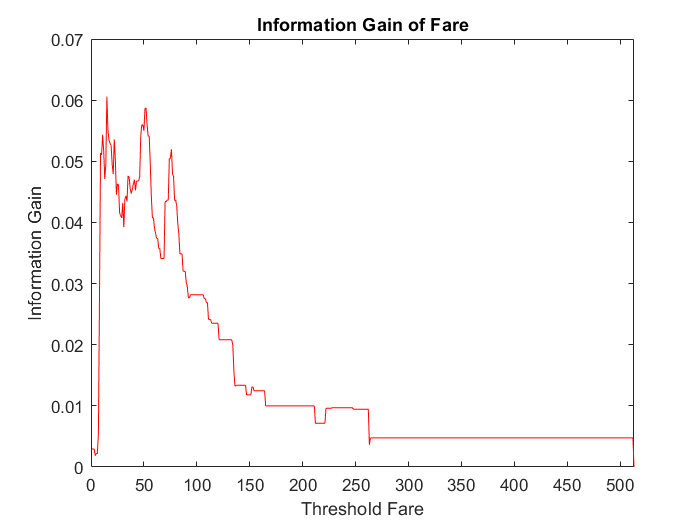

dataFareClass=passengerData_newAttr.survived; % dataClass using survived from newAttr
dataFareClass(isnan(passengerData_newAttr.fare))=[]; % Omit fare missing

for iter=1:513 % for loop using MaxFare
    FareThreshEnt(iter) = calcEntThresh(FareData,dataFareClass,iter); % Calculate Entropy Threshold
end

% Line Plot: Information Gain over Fare from 0 to Maximum Fare 
plot(1:513,FareThreshEnt,'r')
title('Information Gain of Fare')
xlim([0 513])
xlabel('Threshold Fare')
ylabel('Information Gain')

Which attribute provides the highest information gain? Justify your answer.

*Boat_Missing shows the highest information gain. Due to the amount of Boat Missing values is greater than 50%, causing the number of above and below values to be large.*

What would you recommend to use for the first decision? Justify your answer.

*Recommended to use gender of the passenger, because as per Task 1 results we could observe more women survived compared to men.*

Could `is_boat_missing` or `is_body_missing` realistically be used for prediction in future situations? Justify your answer.

*Boat Missing and Body Missing aren't realistically usable due to the fact that those individuals could possibly survive yet not have registered.*

### Part 4: From Decision Trees to Random Forests (25%)

In real applications, we don't typically code our own entropy computation functions from scratch - we instead exploit the multitude of pre-existing libraries.  Here, you will train decision trees and random forests using MATLAB's Statistics and Machine Learning Toolbox.

### Tasks

1. First, use the `cvpartition` function to split your data up into several possible 'training' and 'validation' sets

clc
clearvars -except passengerData_newAttr dataClass

dataClass=categorical(dataClass); % dataClass converted to categorical
c = cvpartition(dataClass,'KFold',10); %10-fold cross validation set
trainIdxes = training(c,1); %Just use the first of the 10 splits
valIdxes = test(c,1);

This performs a 10-fold split of data, i.e. the data is split into training and validation in 10-different non-overlapping ways. Initially, we will just use the first of these splits to fit our decision tree.

a) Take your `passengerData_newAttr` dataset generated in Part 2 and remove all attributes except `{'pclass', 'sex', 'age', 'sibsp', 'parch', 'fare', 'embarked', 'ageMissing'}` to create a new dataset `passengerData_newAttr_partial`*. *You may find the following functions useful:

passengerData_newAttr_partial=removevars(passengerData_newAttr, {'survived', 'name', 'ticket', 'cabin', 'boat', 'body', 'home_dest', 'BoatMissing','BodyMissing'});

b) Next, split `passengerData_newAttr_partial` and the corresponding data classes into a training and validation set (`passengerData_newAttr_train` and `dataClass_train` respectively) using the `trainIdxes` and `valIdxes` arrays generated above.

% Passenger Data Training Data
passengerData_newAttr_train=passengerData_newAttr_partial(trainIdxes,:);
dataClass_train=dataClass(trainIdxes,:);

% Passenger Data Validation Data
passengerData_newAttr_val=passengerData_newAttr_partial(valIdxes,:);
dataClass_val=dataClass(valIdxes,:);

c) Now fit a decision tree using the `fitctree` function and plot it using the `view` function with the name-value argument `'Mode', 'graph'`.  *Note*: you must tell the fitting algorithm which variables are 'categorical', otherwise it assumes all are continuous valued - this can be done using the `'CategoricalPredictors'` argument.

% Decision Tree 
decision_tree=fitctree(passengerData_newAttr_train,dataClass_train,'PredictorNames',{'pclass', 'sex', 'age', 'sibsp', 'parch', 'fare', 'embarked', 'AgeMissing'})

decision_tree =   ClassificationTree
           PredictorNames: {'pclass'  'sex'  'age'  'sibsp'  'parch'  'fare'  'embarked'  'AgeMissing'}
             ResponseName: 'Y'
    CategoricalPredictors: [2 7 8]
               ClassNames: [0    1]
           ScoreTransform: 'none'
          NumObservations: 1044


  Properties, Methods


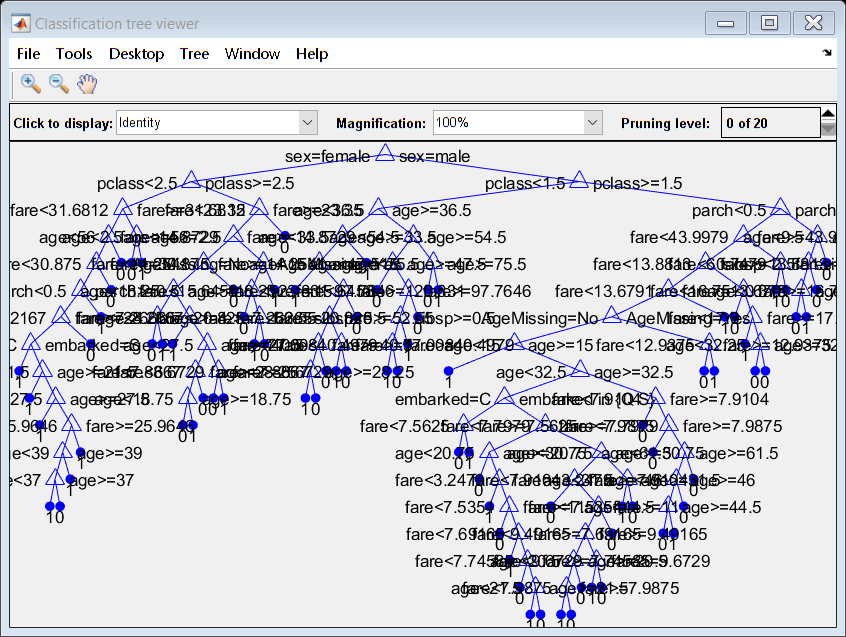

view(decision_tree,'Mode','graph');

impAttr = predictorImportance(decision_tree)

impAttr =     0.0006    0.0017    0.0006    0.0001    0.0000    0.0009    0.0000    0.0000


Looking at the tree, what are the first, second and third most important attributes for determining survival? Justify your answer. You might find it helpful to look up the following function in the MATLAB help:

*Fare, Sex, Age accordingly. These coloumns are important to determine the survival (DataClass) as the results from previous tasks identified the gender fare and age have useful informative information in. This is proven using the impAttr variable where it deemed these variables most important.*

d) Use the *predict* method on the validation set.  For example:

Compute the classification accuracy on the validation set.

estimated=predict(decision_tree,passengerData_newAttr_val); % estimated result 
class_accuracy=nnz(estimated==dataClass_val)/size(estimated,1) % class accuracy using estimated and validation

class_accuracy = 0.7913

2. a) You will now 'prune' your tree. To limit the size of your tree use the '`MaxNumSplits'` name-variable option - consult the MATLAB documentation on `fitctree` for more information.  Try different values for `MaxNumSplits` from 1 to 200 and produce a plot that shows how the classification accuracy changes for both the training and validation sets.  That is, you should produce a plot of classification accuracy vs. MaxNumSplits containing two curves: training data and validation data.  

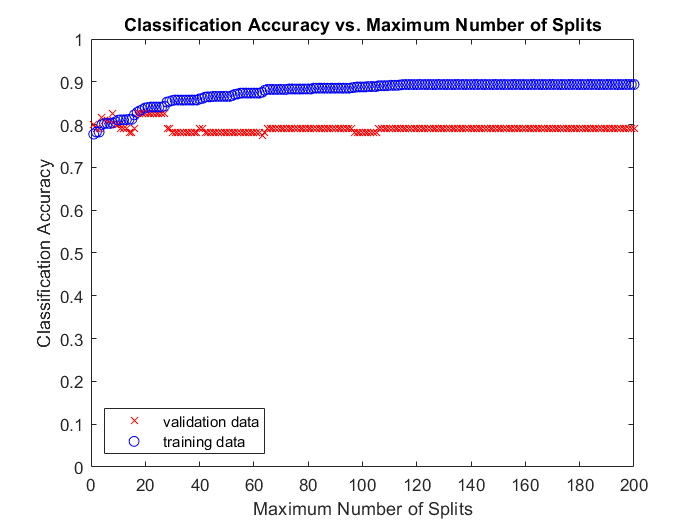

cla reset
maxVal = 200; minVal = 1; %initialize the min and max split values

for splitVal=minVal:maxVal
    
    % generate tree for each split
    tree=fitctree(passengerData_newAttr_train,dataClass_train,'PredictorNames',{'pclass', 'sex', 'age', 'sibsp', 'parch', 'fare', 'embarked', 'AgeMissing'},"MaxNumSplits",splitVal);
    
    % generate CrossVal tree for each split
    treeCV = fitctree(passengerData_newAttr_train,dataClass_train, 'PredictorNames',{'pclass', 'sex', 'age', 'sibsp', 'parch', 'fare', 'embarked', 'AgeMissing'}, "MaxNumSplits",splitVal,'CrossVal','on');
    
    EstVal = predict(tree,passengerData_newAttr_val); % estimated result (validation)
    valError = nnz(EstVal == dataClass_val)/size(dataClass_val,1); % class accuracy using estimated and validation
    cvError(splitVal) = 1 - kfoldLoss(treeCV); % cross validation error
    
    est_train = predict(tree,passengerData_newAttr_train); % estimated result (training)
    trainError = nnz(est_train == dataClass_train)/size(dataClass_train,1); % class accuracy using estimated and training
    
    % Plot error results of validation and training
    plot(splitVal,valError,'rx');
    hold on;
    plot(splitVal,trainError,'bo');

end
ylim([0 1])
title('Classification Accuracy vs. Maximum Number of Splits')
xlabel('Maximum Number of Splits')
ylabel('Classification Accuracy')
legend({'validation data', 'training data'},'Location','southwest');

Based on this graph, what you recommend as a sensible value for `MaxNumSplits`*?* Justify your answer.

*110, because afterward such the values of error remain rather stable*

b) You may notice that if you run your code multiple times, the graph is quite different - this is due to the fact that the `cvpartition` function randomly splits up the data in a different way each time.  A more robust approach is to perform a k-fold cross validation - i.e. produce *k* different splits, calculate the accuracy of each when predicting the training set and then plot the average across the *k* splits.  Modify your code above to use the `CrossVal` method (see documentation for `fitctree`) then plot the accuracy of the k-fold cross-validated model using the `kfoldLoss` function.

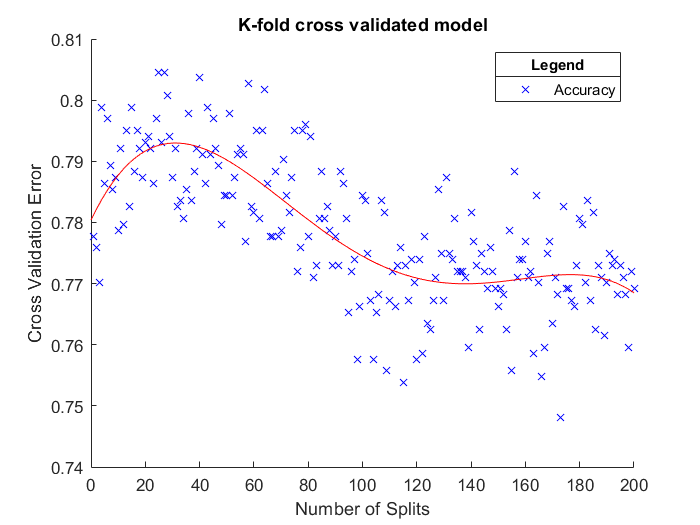

cla reset

% for loop to plot cross validation error from above code
for i=1:200
    hold on
    plot(i,cvError(i),'bx')
end
title('K-fold cross validated model')
xlabel('Number of Splits')
ylabel('Cross Validation Error')

% Polynomial to identify trendline
polFit = polyfit(1:200,cvError,4); 
x_coord = linspace(0,200);
y_coord = polyval(polFit,x_coord);
plot(x_coord,y_coord,'r') %trendline in red
hold off

lgd = legend('Accuracy');
title(lgd,'Legend')

Based on this graph, what you recommend as a sensible value for `MaxNumSplits`? Justify your answer.

*120, as it presents a low CV error and using previous results is above 110 number of splits. After 120 splits the trendline presents a plateau and further decrease in cross-validation error.*

Which of these two estimates would you recommend using for building a model? Justify your answer.

*First as it uses validation and training error and it shows a clear response position where it is deemed to be stable.*

3. Next, we will move from using decision trees to using random forests.  To this, we will use the `TreeBagger` class, which creates a specified number of random trees.  For example:

a) Write code that generates random forests with different numbers of trees, ranging from 1 to 80 trees, and determines the classification error on the validation set in each case. Plot a graph of validation error vs. number of trees in the forest.

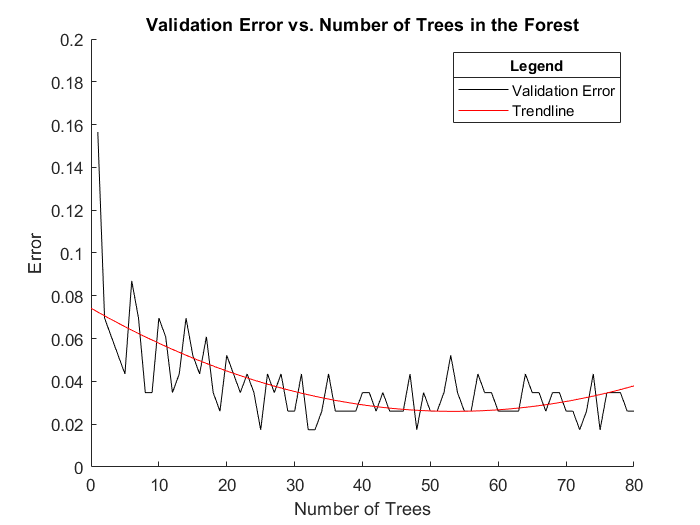

cla reset;

for numberTrees=1:80 % No. of trees with 1 to 80
    
    % treebagger using validation data
    rand_f = TreeBagger(numberTrees,passengerData_newAttr_val,dataClass_val,'Method','classification');
    DataClassEstVal = predict(rand_f,passengerData_newAttr_val); % estimated result (validation)
    valeError(numberTrees) = 1-nnz(DataClassEstVal == dataClass_val)/size(dataClass_val,1); % class accuracy using estimated and validation
    hold on;
    
end

% Line plot of validation error
plot(1:80,valeError,'k')
ylim([0 0.2])
title('Validation Error vs. Number of Trees in the Forest')
xlabel('Number of Trees')
ylabel('Error')
hold on

% Polynomial to identify trendline
polFit = polyfit(1:80,valeError,2); 
x_coord = linspace(0,80);
y_coord = polyval(polFit,x_coord);
plot(x_coord,y_coord,'r')

lgd=legend('Validation Error','Trendline','Location','northeast');
title(lgd,'Legend')

What do you think is the best size of forest to use? Justify your answer.

*The best size of forest is 50, due to the trendline helps us position data in an area between high bias and high variance.*

b) Instead of testing on the validation set, which wastes data as it can't be used for training, you can do something similar to cross-validation that involves testing each tree in the forest on 'out-of-bag' data, i.e. data points that were not used in training that particular tree.  Plot the out-of-bag error vs. number of trees in the forest for values 1 to 80. You may find the following function useful:

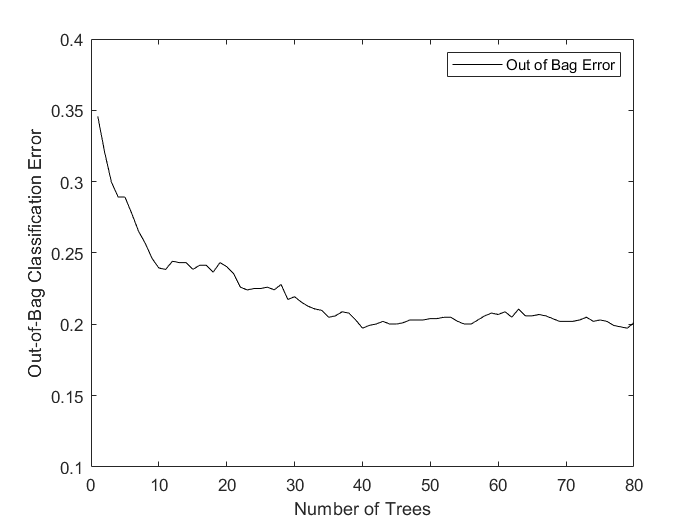

for numberTrees=1:80 % for loop using trees from 1 to 80
    % TreeBagger using training data
    rand_f = TreeBagger(numberTrees,passengerData_newAttr_train,dataClass_train,'Method','classification', 'CategoricalPredictors',{'pclass', 'sex', 'age', 'sibsp', 'parch', 'fare', 'embarked', 'AgeMissing'},"OOBPrediction","on");
end

cla reset
% Line Plot: Out of Bag Classification Error over Trees
plot(1:80,oobError(rand_f),'k','DisplayName','Out of Bag Error')

ylim([0.1 0.4])
xlabel('Number of Trees')
ylabel('Out-of-Bag Classification Error')
legend

Based on the out-of-bag error, what do you think is the best size of tree to use? Justify your answer.

*40 trees, afterwards the out of bag error shows no significant rise/fall in error rate even while increasing number of trees.*

4. a) Using the methods you have developed so far, write code that trains a Random Forest classifier on the full data set in the file passengers.csv and then takes in a second file, passengersVal.csv, that does not contain any survival variable, and performs predictions of survival on these data points. A sample passengersVal.csv file (containing data already in the training set) has been provided. For marking a different data file, containing passenger data not in the original passengers.csv file, will be used to test how well your Random Forest classifer predicts survival. For training and prediction use only the following attributes: `{'pclass', 'sex', 'age', 'sibsp', 'parch', 'fare', 'embarked'}`. To be clear, your final code must read in and perform prediction on the passengersVal.csv file.

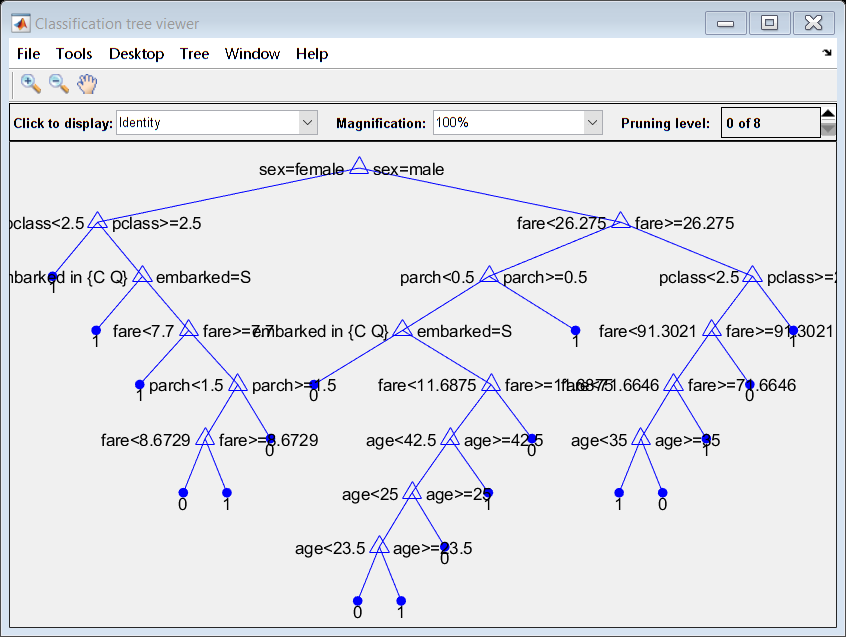

clc; clear; % clear all previous variables

% Assign Tables from CSV
passengerData=readtable('passengers.csv'); 
passengerDataVal=readtable('passengersVal.csv');

% Remove variables
passengerDataVal_partial=removevars(passengerDataVal, {'name', 'ticket', 'cabin', 'boat', 'body', 'home_dest'});
passengerData_partial=removevars(passengerData, {'survived', 'name', 'ticket', 'cabin', 'boat', 'body', 'home_dest'});
dataClass=passengerData.survived; % Set dataClass to complete passengerData survived for training

cv = cvpartition(dataClass,'HoldOut',1009); %10-fold cross validation set
trainIdxes = training(cv,1); 
valIdxes = test(cv,1);

% Passenger Data Training Data
passengerData_train=passengerData_partial(trainIdxes,:);
dataClass_train=dataClass(trainIdxes,:);

decision_tree=fitctree(passengerData_train,dataClass_train,'PredictorNames',{'pclass', 'sex', 'age', 'sibsp', 'parch', 'fare', 'embarked'},"MaxNumSplits",200);
view(decision_tree,'Mode','graph') %view decision tree

% Using random forests to predict survival
rand_f = TreeBagger(80, passengerData_partial, dataClass, "Method","classification","OOBPrediction","on","OOBPredictorImportance","on");

% Predict on new data
predictedSurvival=str2double(rand_f.predict(passengerDataVal_partial))

predictedSurvival =      0
     1
     1
     1
     1
     1
     1
     1
     0
     1


% ~ Compare to original data ~ 

% Initialise variables to get names
names_originaldata=passengerData(:,3); 
name_valdata=passengerDataVal(:,2);


rows=ismember(names_originaldata, name_valdata); %identify position using logical array
[sort1 sort2]= sort(rows, 'ascend'); % sort data 
sorted=sort2(1010:end,1); 
PassengerSorted=passengerData(sorted,:); % Collect Passenger Data to match with data to test against
dataClass_original=table2array(PassengerSorted(:,2)); % convert table to array

correct=0;
for i=1:150
    if predictedSurvival(i)==dataClass_original(i) % identify if same result in each row
       correct=correct+1;
    end
end

disp((correct/size(passengerDataVal,1))*100) % Percentage accuracy compared to original dataset

   95.3333



b) For your trained Random Forest, what are the most important attributes?  To find this out, you may may wish to use the following flags:

Important_Attributes=rand_f.OOBPermutedPredictorDeltaError % Importance of attributes

Important_Attributes =     1.6796    4.8381    1.1312    0.7397    0.8331    1.7727    0.6375


Comment on your answer.

*The key contributing attributes were sex, pclass, fare according from highest to lowest result.*